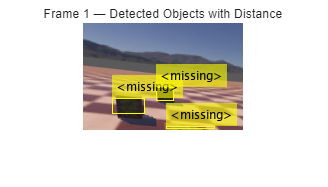

% ────────────────────────────────────────────────
% 0. YOLO 로드 (한 번만)
% ────────────────────────────────────────────────
if ~exist("yoloDet","var") || isempty(yoloDet)
    yoloFile = "detector_nao.mat";
    fprintf("Loading YOLO detector from %s ...\n", yoloFile);
    tmp      = load(yoloFile, "detector");
    yoloDet  = tmp.detector;
    fprintf("YOLO detector loaded ✔︎\n\n");
end

% ────────────────────────────────────────────────
% 1. 스테레오 파라미터 로드
% ────────────────────────────────────────────────
load("handshakeStereoParams.mat");  % stereoParams 객체가 있다고 가정

% ────────────────────────────────────────────────
% 2. 이미지 파일 목록 로드 및 정렬
% ────────────────────────────────────────────────
folderL = "resource/img/top_l";
folderR = "resource/img/top_r";

filesL = dir(fullfile(folderL, "frame_*.png"));
filesR = dir(fullfile(folderR, "frame_*.png"));

% 정렬 (frame_1.png, frame_2.png, ...)
extractFrameNum = @(name) sscanf(name, 'frame_%d.png');
[~, idxL] = sort(arrayfun(@(f) extractFrameNum(f.name), filesL));
[~, idxR] = sort(arrayfun(@(f) extractFrameNum(f.name), filesR));

filesL = filesL(idxL);
filesR = filesR(idxR);

nFrames = min(length(filesL), length(filesR));

% ────────────────────────────────────────────────
% 3. 반복 처리
% ────────────────────────────────────────────────
for i = 1:nFrames
    % 이미지 불러오기
    frameLeft  = imread(fullfile(folderL, filesL(i).name));
    frameRight = imread(fullfile(folderR, filesR(i).name));

    % 3.1 스테레오 보정 (Rectification)
    [frameLeftRect, frameRightRect, reprojectionMatrix] = ...
        rectifyStereoImages(frameLeft, frameRight, stereoParams);

    % 3.2 disparity map 생성
    frameLeftGray  = im2gray(frameLeftRect);
    frameRightGray = im2gray(frameRightRect);
    disparityMap   = disparitySGM(frameLeftGray, frameRightGray);

    % 3.3 3D scene 재구성
    points3D = reconstructScene(disparityMap, reprojectionMatrix);
    points3D = points3D ./ 1000;  % mm → m

    % 3.4 YOLO 객체 탐지 (왼쪽 영상 기준)
    [bboxes, scores, labels] = detect(yoloDet, frameRightRect, Threshold=0.25);

    if isempty(bboxes)
        fprintf("No objects detected in frame %d\n", i);
        continue;
    end

    % 3.5 중심점 계산
    centroids = [round(bboxes(:,1) + bboxes(:,3)/2), ...
                 round(bboxes(:,2) + bboxes(:,4)/2)];

    % 중심점의 3D 좌표 추출
    centroidsIdx = sub2ind(size(disparityMap), centroids(:,2), centroids(:,1));
    X = points3D(:, :, 1);  Y = points3D(:, :, 2);  Z = points3D(:, :, 3);
    centroids3D = [X(centroidsIdx)'; Y(centroidsIdx)'; Z(centroidsIdx)'];

    % 거리 계산
    dists = sqrt(sum(centroids3D .^ 2));

    % 결과 라벨
    distLabels = dists + " meters";

    % 시각화
    annotatedImg = insertObjectAnnotation(frameRightRect, "rectangle", bboxes, distLabels);
    figure(1); imshow(annotatedImg);
    title(sprintf("Frame %d — Detected Objects with Distance", i));
    drawnow;
end